clc
clear all
close all
pause('off')

# Homework 2

# Japnit Sethi

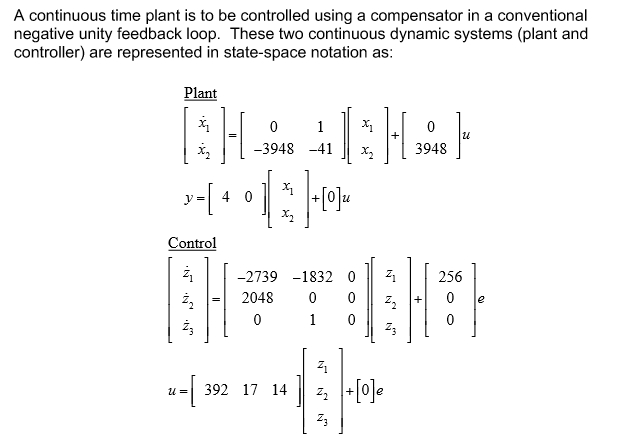

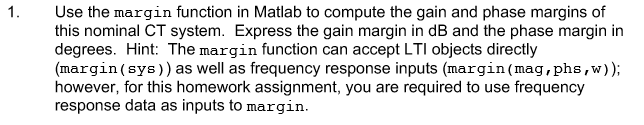

## **Solution**:

**Note**: Transfer functions are least numerically robust models so do not convert straight to tf from state space.

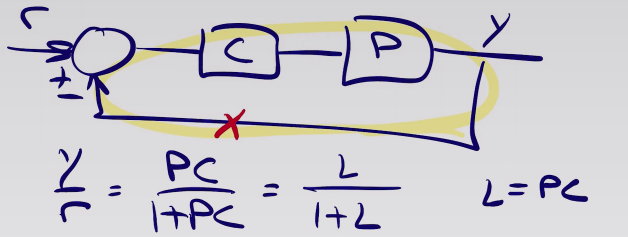

% Problem 1

% Plant
A_Plant = [0, 1; -3948, -41];
B_Plant = [0; 3948];
C_Plant = [4, 0];
D_Plant = 0;

% Compensator
A_Compensator = [-2739, -1832, 0; 2048, 0, 0; 0, 1, 0];
B_Compensator = [256; 0; 0];
C_Compensator = [392, 17, 14];
D_Compensator = 0;

% Dynamic state space model
sys_Plant = ss(A_Plant, B_Plant, C_Plant, D_Plant);

% Dynamic state space model and transfer function of compensator
sys_Compensator = ss(A_Compensator, B_Compensator, C_Compensator, D_Compensator);

closed_loop = sys_Plant*sys_Compensator;

fr = logspace(-2,4,10000); % frequency range of 10^-3 to 10^4 with 10000 data points in bw

% Don't need freq response of plant and compensator but anyways:
P = squeeze(freqresp(sys_Plant,2*pi*fr));
C = squeeze(freqresp(sys_Compensator,2*pi*fr));

% Frequency response on the real frequency grid specified by vector 2*pi*fr
lpf = squeeze(freqresp(closed_loop,2*pi*fr)); 

mag = abs(lpf); % magnitude in absolute units
phs = (180/pi)*angle(lpf); % Phase angle in degrees

% get the gain and phase margins:
[Gain_Margin,Phase_Margin,Wc_gain,Wc_phase] = margin(mag,phs,2*pi*fr);

% Note: Can also just use closed_loop instead of freqresp data mag and phase
% [Gain_Margin,Phase_Margin,Wc_gain,Wc_phase] = margin(closed_loop,2*pi*fr);


% display the gain and phase margins in appropriate units:
Gain_Margin_dB = 20*log10(Gain_Margin)

Gain_Margin_dB = 15.9157

Phase_Margin_degrees = Phase_Margin 

Phase_Margin_degrees = 65.3894

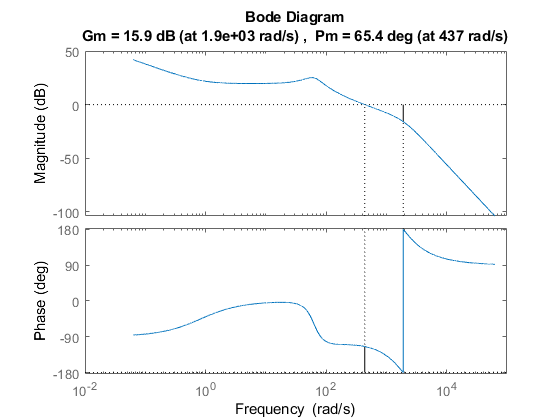


% Bode plot with Gain and Phase Margins
margin(mag,phs,2*pi*fr)

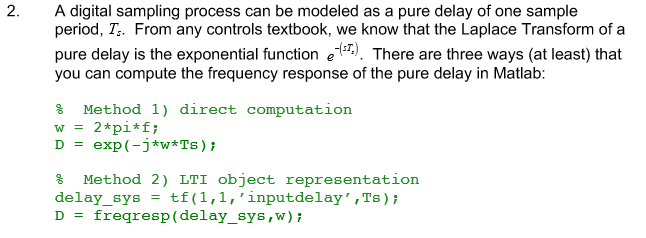

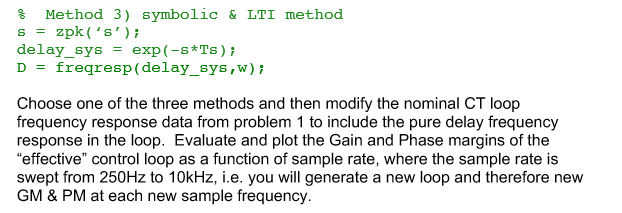

## **Solution**:

Note: Here my r, error, y are all in analog form

The positioning of delay [ADC & DAC] will not effect the phase and gain margin

Positioning of ADC and DAC (check )

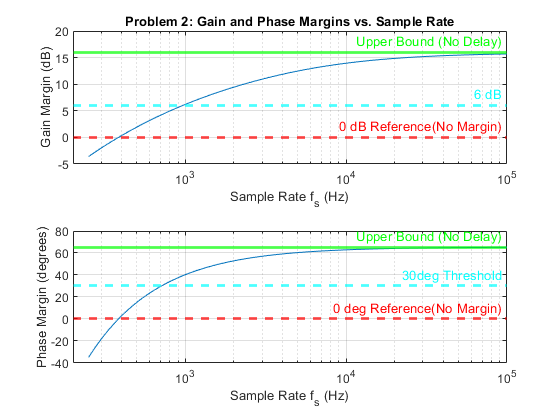

% Problem 2

N = 100;
fs = logspace(log10(250), 5, N); % Frequency logarithmic scale , 250 to 10^5
N = length(fs);
ts = 1./fs;
fr = logspace(-2,4,10000); % frequency range of 10^-3 to 10^4 with 10000 data points in bw
w = 2*pi*fr;

GM = zeros(1,N); PM = zeros(1,N);

method = 3;

for i = 1:N
    switch method
        case 1
            D = transpose(exp(-j*w*ts(i)));
        case 2 
            delay = tf(1,1, 'inputdelay', ts(i));
            D = squeeze(freqresp(delay, w));
        case 3
            s = zpk('s');
            delay = exp(-ts(i)*s);
            D = squeeze(freqresp(delay, w));
    end

    L = lpf.*D;
    mag = abs(L);
    phase = (180/pi)*angle(L);

    [Gm, Pm_deg] = margin(mag, phase, w);
    Gm_db = 20*log10(Gm);

    GM(i) = Gm_db;
    PM(i) = Pm_deg;
end

figure()
subplot(2,1,1) % plotting the gain margin
semilogx(fs,GM)
grid on
% 0 dB Horizontal Reference line 
yline(0, '--r', '0 dB Reference(No Margin)', 'LineWidth', 2);
yline(6, '--c', '6 dB', 'LineWidth', 2);
yline(15.9157, '-g', 'Upper Bound (No Delay)', 'LineWidth', 2);
xlabel('Sample Rate f_{s} (Hz)');
ylabel('Gain Margin (dB)');
title('Problem 2: Gain and Phase Margins vs. Sample Rate');
xlim([200, 1e5]);
ylim([-5, 20]);

subplot(2,1,2) % plotting the phase margin
semilogx(fs, PM)
grid on
yline(0, '--r', '0 deg Reference(No Margin)', 'LineWidth', 2);
yline(30, '--c', '30deg Threshold', 'LineWidth', 2);
yline(65.3894, '-g', 'Upper Bound (No Delay)', 'LineWidth', 2);
xlabel('Sample Rate f_{s} (Hz)');
ylabel('Phase Margin (degrees)');
ylim([-40, 80]);
xlim([200, 1e5]);

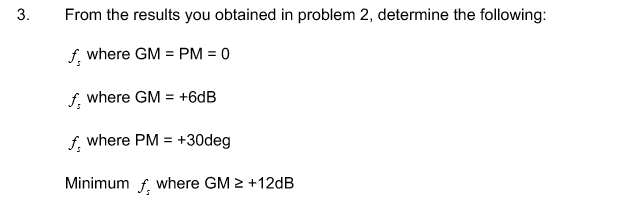

**Solution:**

Plotted in the Previous plot itself-

a) Frequency at GM = PM = 0 is 384.3 Hz

b) Frequency at GM = +6 dB is 962 Hz

c) Frequency at PM = +30 Hz is 709.6 Hz

d) Minimum Frequency where GM $\ge$ +12 dB is 4298 Hz

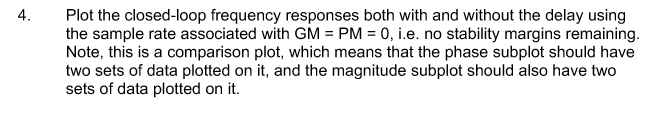

Note: The positioning of delay is important and thus have an effect in this problem

Note: The loop transfer function does not change

Case 1: Delay in the forward path

$L_1 =D_1 *C*P$,  $\Longrightarrow$ $\frac{Y}{r}=\frac{L_1 }{1+L_1 }$

Case 2: Delay in the backward loop


$$L_2 =D_2 *C*P$$
 
$$\Longrightarrow$$
 
$$\frac{Y}{r}=\frac{C*P}{1+L_2 }$$


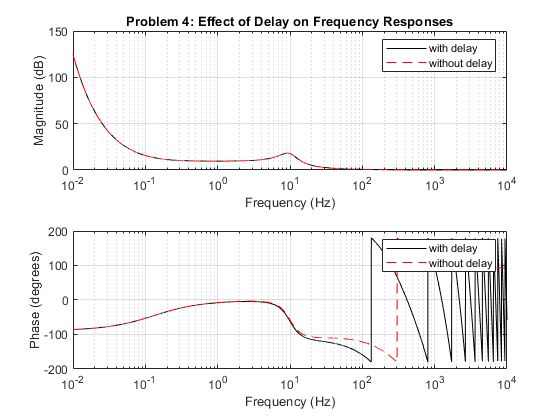

% Problem 4


% Without Delay from Problem 1
mag_wihtoutDelay = abs(lpf); % magnitude in absolute units
phs_wihtoutDelay = (180/pi)*angle(lpf); % Phase angle in degrees

% With Delay Using Method from Problem 2
N = 100;
fs = 960; % Because sample rate is 960 Hz
ts = 1/fs;
fr = logspace(-2,4,10000); % frequency range of 10^-3 to 10^4 with 10000 data points in bw
w = 2*pi*fr;

method = 3;

for i = 1:N
    switch method
        case 1
            D = transpose(exp(-j*w*ts));
        case 2 
            delay = tf(1,1, 'inputdelay', ts);
            D = squeeze(freqresp(delay, w));
        case 3
            s = zpk('s');
            delay = exp(-ts*s);
            D = squeeze(freqresp(delay, w));
    end

    L = lpf.*D;
    mag_withDelay = abs(L);
    phase_withDelay = (180/pi)*angle(L);
end


% Plot the comparison of response with and without delay
% magnitude comparison
figure()
subplot(2,1,1) 
semilogx(fr,mag_withDelay,'k');
hold on
grid on
semilogx(fr,mag_wihtoutDelay,'r --');
hold off
legend('with delay', 'without delay');
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Problem 4: Effect of Delay on Frequency Responses')
xlim([0, 10000]);

% phase comparison
subplot(2,1,2) 
semilogx(fr,phase_withDelay,'k');
hold on
grid on
semilogx(fr,phs_wihtoutDelay,'r --');
hold off
legend('with delay', 'without delay');
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')
xlim([0, 10000]);

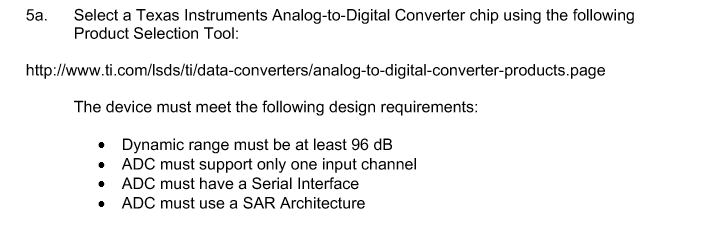

Solution:

R = 20log10($\frac{2^{\mathrm{NBITS}} -1}{1}$)$\ge$96dB    $\Longrightarrow$  NBITS $\ge$ $\frac{\mathrm{ln}\left(1+{10}^{\left(\frac{96}{20}\right)} \right)}{\mathrm{ln}\left(2\right)}$  = 15.945

**The chosen ADC chips are:**

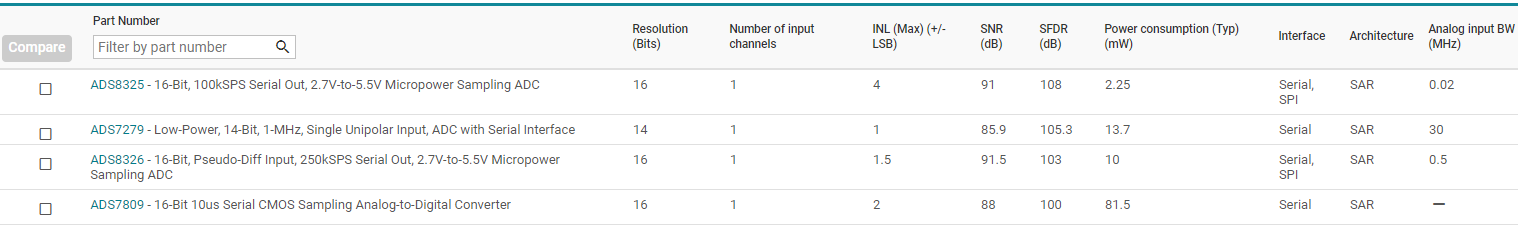

% Problem 5b

disp(' ')

disp('(1) ADS8325')

(1) ADS8325



disp('Input Voltage Range (Unipolar Operation) (given): 5 volts')

Input Voltage Range (Unipolar Operation) (given): 5 volts


disp('Number of Bits (given): 16 bits')

Number of Bits (given): 16 bits


Q1 = 5/(2^16 - 1);
Rdb1 = 20*log10(2.8/Q1);
disp(['Resolution: ', num2str(Q1), ' volts.']);

Resolution: 7.6295e-05 volts.


disp(['Dynamic Range: ', num2str(Rdb1), 'dB.']);

Dynamic Range: 91.2932dB.



disp(' ')

disp('(2) ADS8326')

(2) ADS8326



disp('Input Voltage Range (Unipolar Operation) (given): 5 volts')

Input Voltage Range (Unipolar Operation) (given): 5 volts


disp('Number of Bits (given): 16 bits')

Number of Bits (given): 16 bits


Q3 = 5/(2^16 - 1);
Rdb3 = 20*log10(2.8/Q3);
disp(['Resolution: ', num2str(Q3), ' volts.']);

Resolution: 7.6295e-05 volts.


disp(['Dynamic Range: ', num2str(Rdb3), 'dB.']);

Dynamic Range: 91.2932dB.



disp(' ')

disp('(3) ADS7809')

(3) ADS7809



disp('Input Voltage Range (Unipolar Operation) (given): 5 volts')

Input Voltage Range (Unipolar Operation) (given): 5 volts


disp('Number of Bits (given): 16 bits')

Number of Bits (given): 16 bits


Q4 = 5/(2^16 - 1);
Rdb4 = 20*log10(5/Q4);
disp(['Resolution: ', num2str(Q4), ' volts.']);

Resolution: 7.6295e-05 volts.


disp(['Dynamic Range: ', num2str(Rdb4), 'dB.']);

Dynamic Range: 96.3295dB.
